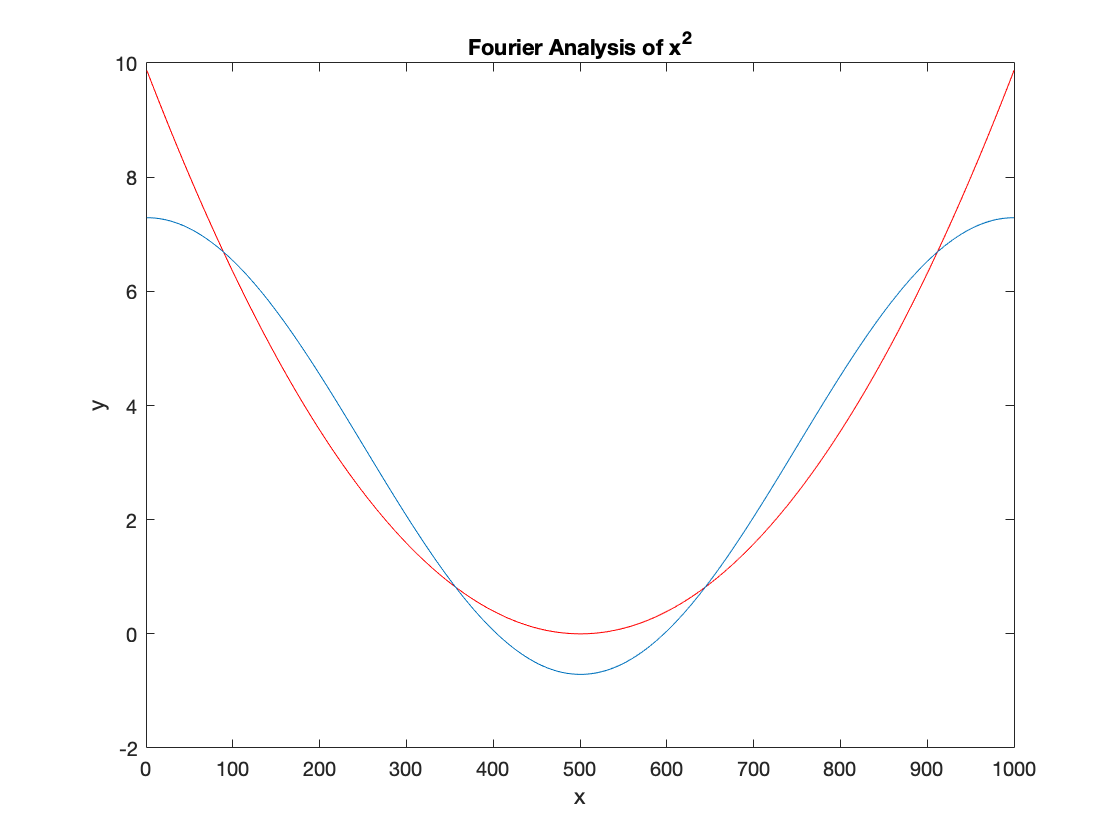

syms z
%plot x^2%
x = linspace(-pi,pi,1000);
f = x.^2;
plot(f,'red')
hold on
%user input
g = 0;
deg = input('how many iterations do u want');
%coefficents were calculated by hand using integration
for i= 1:1:deg
    a = (1/pi) * int((z^2) * cos(i * z),z, -pi, pi);
    b = (1/pi) * int((z^2) * sin(i * z),z, -pi, pi);
    a0 = (1 / (2 * pi)) * int(z^2,z, -pi, pi);
    g = g + a*(cos(i * x) + b * sin(i * x));
    plot(g + a0)
    hold on

title('Fourier Analysis of x^2')
xlabel('x')
ylabel('y')
end